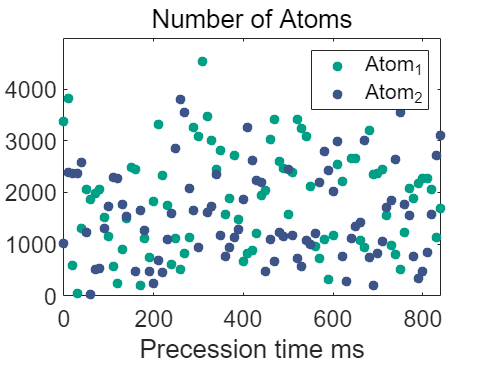

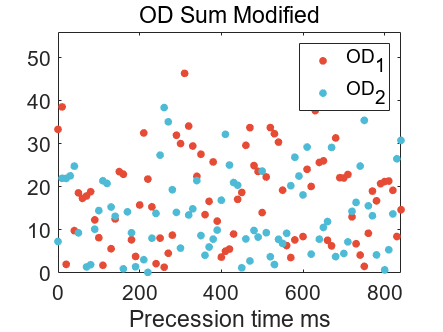

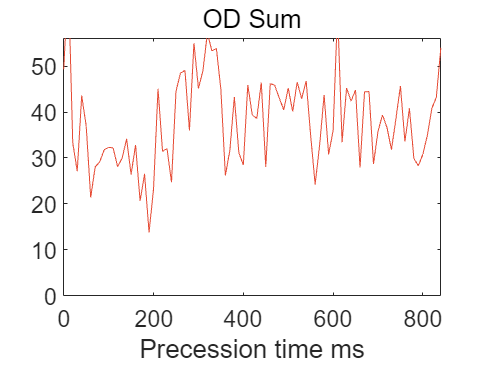

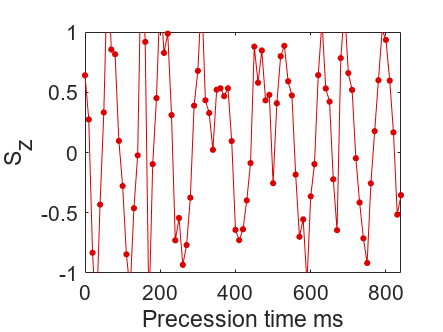

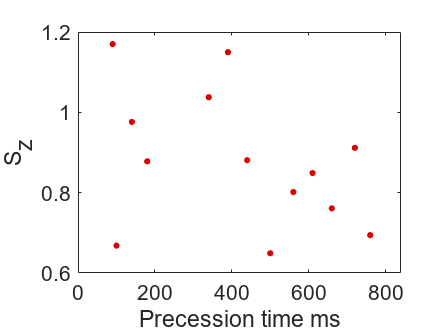


close all
clear all
colors=npg(10); % Ten basic colors 
maindir='\\Artemis-pc\e\Data\2023-11-28\Abs-263\';
main_dir_0=maindir;
load([maindir,'\result.mat']);

%load([maindir,'\Fit.mat']);


## Precession


close all

x_label = 'Precession (ms)';

y_lim_low = -1;
y_lim_high = 1;

x1 = [180];
xlist = 0:10:160;

x_lim_low = min(xlist)*0.95;
x_lim_high = max(xlist)*1.05;

relativeOD = (s1-s2)./(s1+s2);
repeat_se = length(relativeOD)/(length(x1)*length(xlist));
reshape_phase = reshape(relativeOD,length(xlist),repeat_se);


## Precession


f1 = figure;hold on;

for i = 1:repeat_se
    %plot(xlist,reshape_phase(:,i),'*');

    [xData, yData] = prepareCurveData(xlist,reshape_phase(:,i));

    % 设置 fittype 和选项。
    ft = fittype( 'a*sin(2*pi*x/T+b)+c', 'independent', 'x', 'dependent', 'y' );
    opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
    opts.Display = 'Off';
    opts.Lower = [70 0.4 -2*pi -5];
    opts.StartPoint = [100 0.9 0.9 0.9];

    % 对数据进行模型拟合。
    [fitresult, gof] = fit(xData, yData, ft, opts);
    T(i) = fitresult.T;
    a(i) = fitresult.a;
    interval = confint(fitresult);
    a_sigma(i) = (interval(2,2)-interval(1,2))/4;
    T_sigma(i) = (interval(2,1)-interval(1,1))/4;



    % 绘制数据拟合图。
    
    l = plot(fitresult, xData, yData);

    l(1).Marker = 'square';
    l(1).MarkerSize = 6;
    l(1).MarkerEdgeColor = colors(i,:);
    l(1).MarkerFaceColor = colors(i,:);
    l(2).Color = colors(i,:);
    l(2).LineWidth = 2;

    xlabel( 'Precession ms' );
    ylabel( 'S_z' );
    %title(['Precession ',num2str(x1(k)),'s']);
    %set(gca,'FontSize',18,'child',[l(1),l(2)]);

    grid on;
end

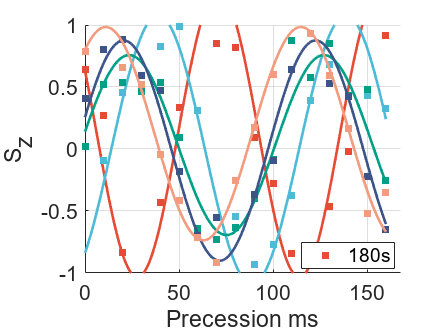


xlim([x_lim_low x_lim_high]);
ylim([y_lim_low y_lim_high]);
hold off;
%legend('10s','','25s','','Location','best');
legend('180s','','Location','best');
set(gca,'fontsize',16);

## ROT


close all

x_label = 'Pulse (us)';

y_lim_low = 0;
y_lim_high = 1;

x1 = [55];
xlist = 700:30:1000;

x_lim_low = min(xlist)*0.95;
x_lim_high = max(xlist)*1.05;

relativeOD = (s1-s2)./(s1+s2);
repeat_se = length(relativeOD)/(length(x1)*length(xlist));
reshape_phase = reshape(relativeOD,length(xlist),repeat_se);


## ROT


f1 = figure;hold on;

for i = 1:repeat_se
    %plot(xlist,reshape_phase(:,i),'*');

    [xData, yData] = prepareCurveData(xlist,reshape_phase(:,i));

    % 设置 fittype 和选项。
    ft = fittype( 'a*sin(2*pi*x/T+b)+c', 'independent', 'x', 'dependent', 'y' );
    opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
    opts.Display = 'Off';
    opts.Lower = [100 0 -2*pi -5];
    opts.StartPoint = [200 0.5 0.9 0.5];

    % 对数据进行模型拟合。
    [fitresult, gof] = fit(xData, yData, ft, opts);
    T(i) = fitresult.T;
    a(i) = fitresult.a;
    interval = confint(fitresult);
    a_sigma(i) = (interval(2,2)-interval(1,2))/4;
    T_sigma(i) = (interval(2,1)-interval(1,1))/4;



    % 绘制数据拟合图。
    
    l = plot(fitresult, xData, yData);

    l(1).Marker = 'square';
    l(1).MarkerSize = 6;
    l(1).MarkerEdgeColor = colors(i,:);
    l(1).MarkerFaceColor = colors(i,:);
    l(2).Color = colors(i,:);
    l(2).LineWidth = 2;

    xlabel( 'Pulse us' );
    ylabel( 'OD_2/OD_1' );
    %title(['Precession ',num2str(x1(k)),'s']);
    %set(gca,'FontSize',18,'child',[l(1),l(2)]);

    grid on;
end

xlim([x_lim_low x_lim_high]);
ylim([y_lim_low y_lim_high]);
hold off;
%legend('10s','','25s','','Location','best');
legend('1','2','Location','best');
set(gca,'fontsize',16);


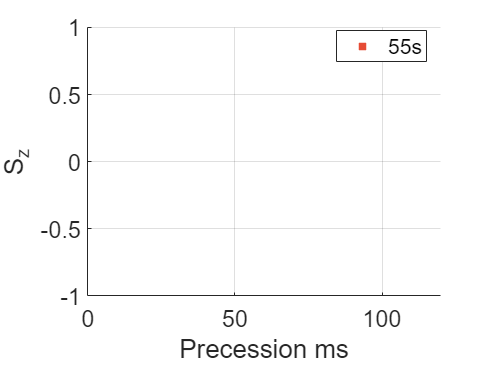


savefig(f1,[main_dir_0,'Drift.fig']);
saveas(f1,[main_dir_0,'Drift.png']);

save([main_dir_0,'\Drift.mat']);